# Time Series Forecasting with LSTMs

This example shows how to forecast time series data using a long short-term memory (LSTM) network. We will forecast the number of chickenpox cases given the number of cases in previous months. 

To forecast the values of future time steps of a sequence, you can train a sequence-to-sequence regression LSTM network, where the responses are the training sequences with values shifted by one time step. That is, at each time step of the input sequence, the LSTM network learns to predict the value of the next time step.

## Load Sequence Data

Load the example data. `chickenpox_dataset` contains a single time series, with time steps corresponding to months and values corresponding to the number of cases. The output is a cell array, where each element is a single time step. Reshape the data to be a row vector.

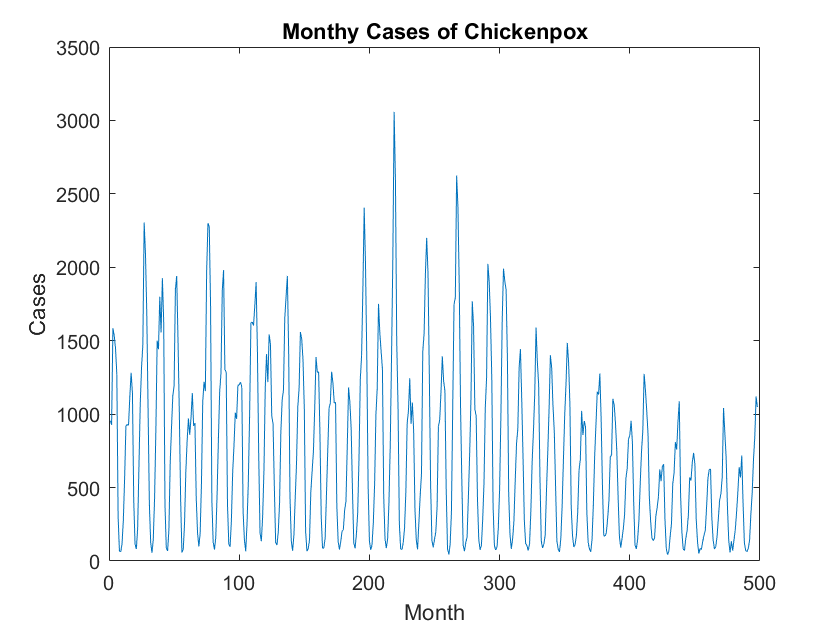

data = chickenpox_dataset;
data = [data{:}];

figure
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthy Cases of Chickenpox")

## Partition Dataset

Partition the training and test data. Train on the first 90% of the sequence and test on the last 10%.

trainingPercentage = 90;

numTimeStepsTrain = floor(0.01 * trainingPercentage * numel(data));

To forecast the values of future time steps of a sequence, specify the responses to be the training sequences with values shifted by one time step.

In this example, XTrain contains our training data. YTrain contains the value that we are trying to predict after a given XTrain value. This means it will always contain data that is one time step ahead of XTrain.

The same logic applies for XTest and YTest.

XTrain = data(1:numTimeStepsTrain);
YTrain = data(2:numTimeStepsTrain+1);

XTest = data(numTimeStepsTrain+1:end-1);
YTest = data(numTimeStepsTrain+2:end);

%plotTrainAndTest

## Standardize Data

For a better fit and to prevent the training from diverging, standardize the training and test data to have zero mean and unit variance. 

mu = mean(XTrain);
sig = std(XTrain);

XTrain = (XTrain - mu) / sig;
YTrain = (YTrain - mu) / sig;

XTest = (XTest - mu) / sig;

## **Define LSTM Network Architecture**

Create an LSTM regression network. Try changing the number of hidden units and see how the network responds.

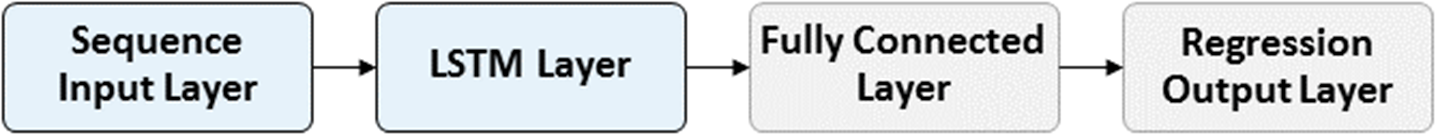

inputSize = 1;
numResponses = 1;

Hidden units are represented by a vector that stores information about the network's current state. The number of hidden units can be thought of as the amount of information stored about previous time steps by the network - more hidden units would mean more information stored. If we have too few hidden units, the network will not store enough information to make accurate predictions and if we have too many, the network will overfit to our training data. You can try to drastically change the number of hidden units and see how the network performs. 

numHiddenUnits = 211;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];   

You can also create the LSTM network using the deep network designer.

% deepNetworkDesigner

## Specify Training Options

Set the solver to `'adam'` and train for 250 epochs. To prevent the gradients from exploding, set the gradient threshold to 1. Specify the initial learn rate 0.005, and drop the learn rate after 125 epochs by multiplying by a factor of 0.2.

Visit the [trainingOptions documentation page](https://www.mathworks.com/help/nnet/ref/trainingoptions.html?searchHighlight=trainingOptions&s_tid=doc_srchtitle) for more information about these name-value arguments. 

opts = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

## Train LSTM Network

Train the LSTM network with the specified training options by using `trainNetwork`. 

You'll notice that the top plot does not calculate accuracy, but rather RMSE. This is the metric used to evaluate network accuracy when doing deep learning for regression.

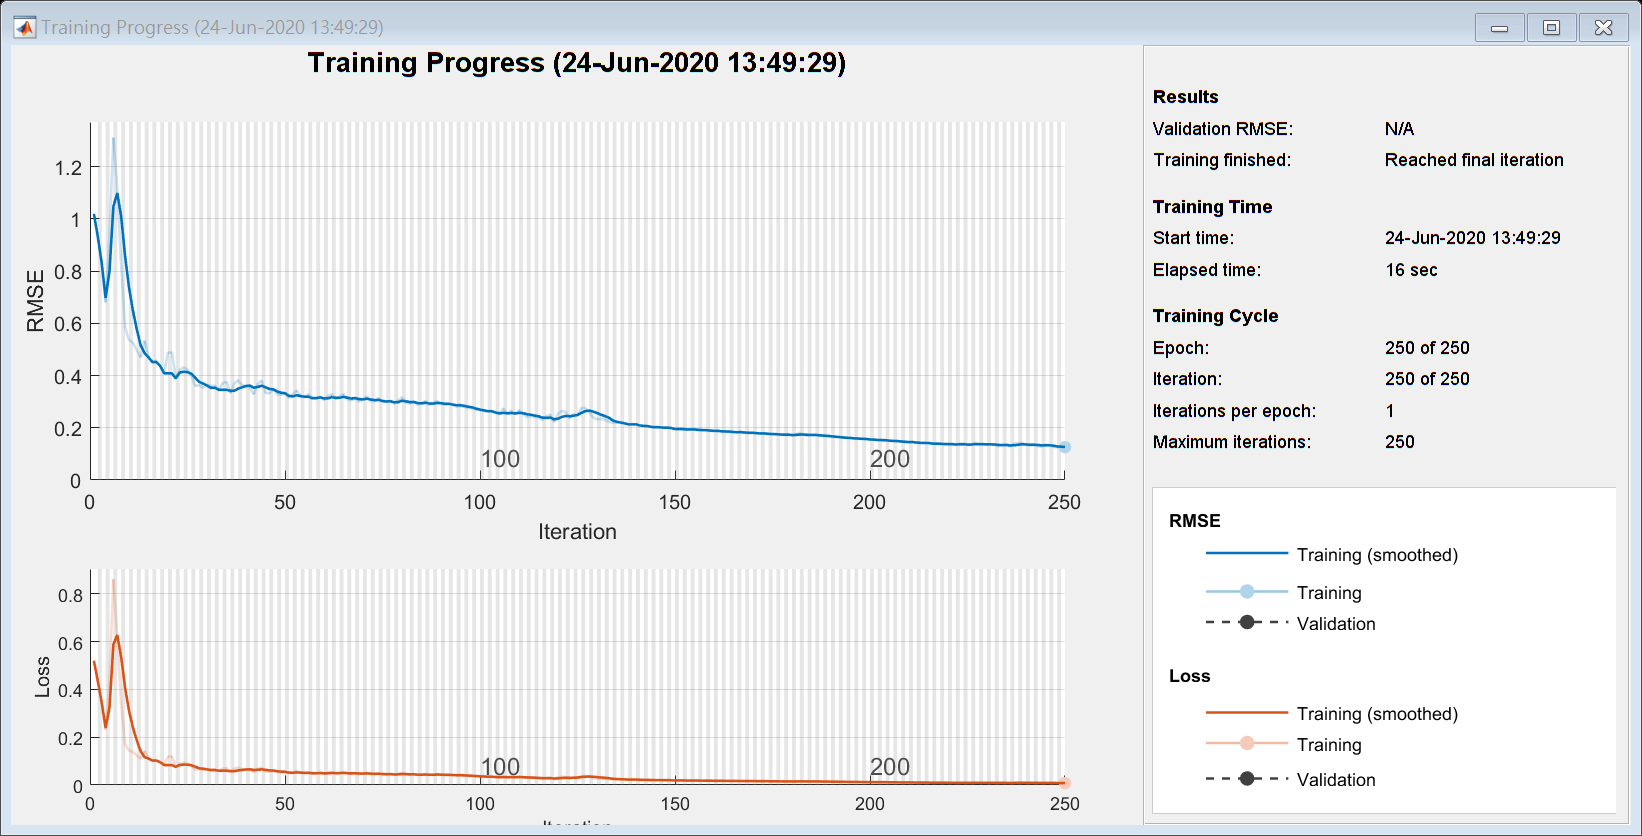

net = trainNetwork(XTrain,YTrain,layers,opts);

## Understanding Network State

When performing time-series forecasting with LSTMs, the network will always have a certain state. The state of the network is determined by what information the network is using to make its prediction(s). This information is stored in the hidden units for that time step. For example, we would use the state of the network at time step 400 to predict the value at time step 401. If we wanted to predict time step 402, we would update the network's state from time step 400 to 401 and use the new state to predict the 402nd value.

Updating the state does not require retraining the network.

## Forecast Future Time Steps

To forecast the values of multiple time steps in the future, use the `predictAndUpdateState` function to predict time steps one at a time and update the network state at each prediction. For each prediction, use the previous prediction as input to the function.

To initialize the network state, first predict on the training data `XTrain`. Next, make the first prediction using the last time step of the training response `YTrain(end)`. Loop over the remaining predictions and input the previous prediction to `predictAndUpdateState`.

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,YPred(i-1));
end

Unstandardize the predictions using `mu` and `sig` calculated earlier.

YPred = sig*YPred + mu;

The training progress plot reports the root-mean-square error (RMSE) calculated from the standardized data. Calculate the RMSE from the unstandardized predictions.

rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
181.0473

Plot the training time series with the forecasted values.

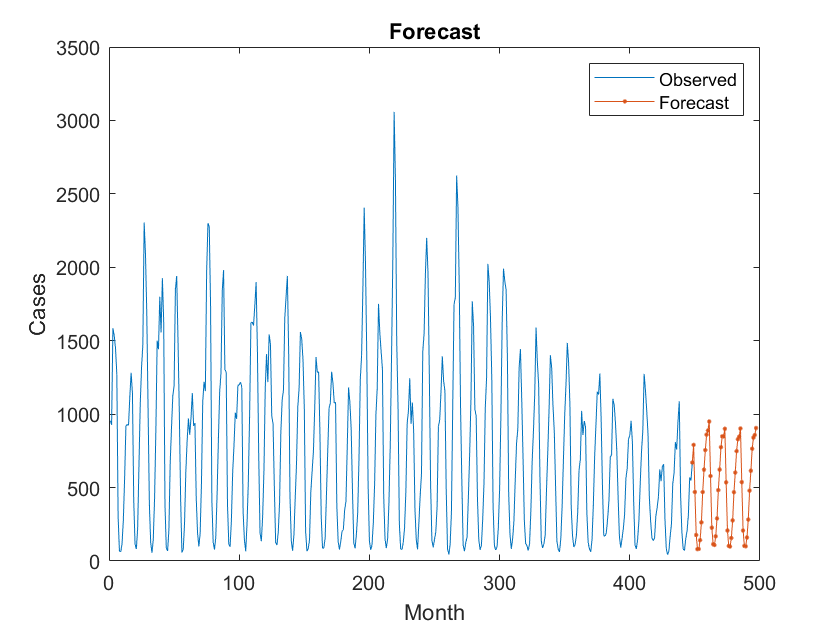

figure
plot(data(1:numTimeStepsTrain))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

Compare the forecasted values with the test data.

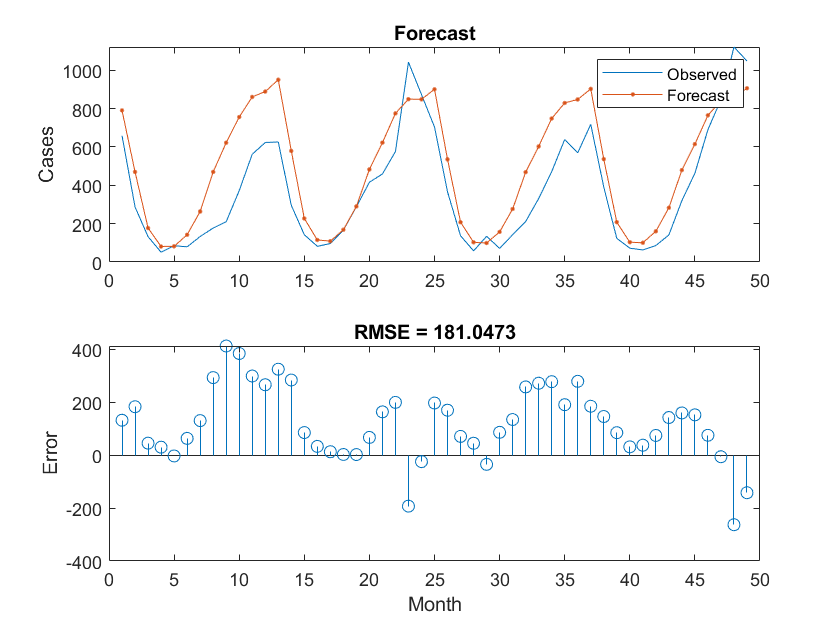

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

## Update Network State with Observed Values

If you have access to the actual values of time steps between predictions, then you can update the network state with the observed values instead of the predicted values.

First, initialize the network state. To make predictions on a new sequence, reset the network state using `resetState`. Resetting the network state prevents previous predictions from affecting the predictions on the new data. Reset the network state, and then initialize the network state by predicting on the training data.

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

Predict on each time step. For each prediction, predict the next time step using the observed value of the previous time step.

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,XTest(i));
end

Unstandardize the predictions using `mu` and `sig` calculated earlier.

YPred = sig*YPred + mu;

Calculate the root-mean-square error (RMSE).

rmse = sqrt(mean((YPred-YTest).^2))

rmse = 115.8858

Compare the forecasted values with the test data.

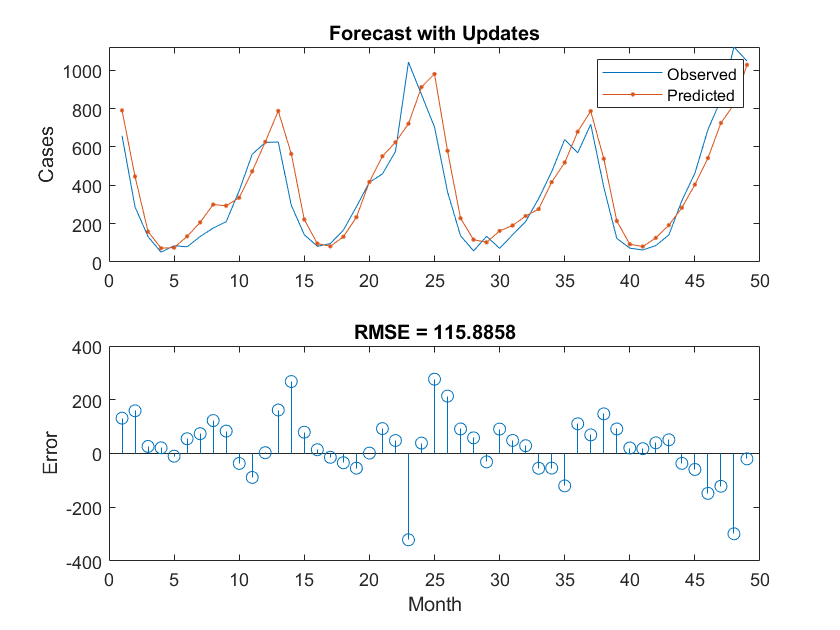

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

Here, the predictions are more accurate when updating the network state with the observed values instead of the predicted values.